clc;clear;

    %real_time_AOA直射径纯净版

% 打开原文件和新文件
fid_in = fopen('.\Data\金属反射探究距离算法\dis3.0.log', 'r');
fid_out = fopen('.\Data\金属反射探究距离算法\dis3.0.txt', 'w');

% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

错误使用 feof
文件标识符无效。使用 fopen 生成有效的文件标识符。


% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

% 读取文本文件
filename = '.\\Data\\data_for_doubleAOA_new\\localization\\processed_rtt_files\\processed_test30_14.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);

% 获取行内容
lines = rawData{1};



% 初始化存储变量
rxenable_status = [];


frame_len = [];
pdoa_val = [];
degrees_val = [];

FPI = [];

% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    % 解析 dwt_rxenable status
    if contains(line, 'dwt_rxenable status')
        tokens = regexp(line, 'dwt_rxenable status\s+0x([0-9A-Fa-f]+)', 'tokens');
        if ~isempty(tokens)
            rxenable_status = [rxenable_status, hex2dec(tokens{1}{1})];
        end
    end
    
    % 解析 Frame Received len
    if contains(line, 'Frame Received len')
        tokens = regexp(line, 'Frame Received len\s+(\d+)', 'tokens');
        if ~isempty(tokens)
            frame_len = [frame_len, str2double(tokens{1}{1})];
        end
    end

    if contains(line, 'First Path Index')
    tokens = regexp(line, 'First Path Index\s+(\d+)', 'tokens');
    if ~isempty(tokens)
        FPI = [FPI, str2double(tokens{1}{1})/64];
    end
end

    
    % 解析 PDOA val 和 Degrees
    if contains(line, 'PDOA val')
        tokens = regexp(line, 'PDOA val\s*=\s*(\d+),\s*Degrees\s*=\s*([-+]?[0-9]*\.?[0-9]+)', 'tokens');
        if ~isempty(tokens)
            pdoa_val = [pdoa_val,str2double(tokens{1}{1})];
            degrees_val = [degrees_val,str2double(tokens{1}{2})];
        end
    end
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% % 输出到命令行确认
% disp(['dwt_rxenable status: ', num2str(rxenable_status)]);
% disp(['Frame Received len: ', num2str(frame_len)]);
% disp(['PDoA: ', num2str(pdoa_val)])

pdoa_values_main = [];
degree_values_main = [];


peaks_index_STS0 = [];

peaks_index_STS1 = [];



packets_num = length(STS0_CIR)/512

packets_num = 142

STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';

STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;

% antennaSpacing = 0.0208;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% phase_offset = 0.26;
%0.26, 0.17

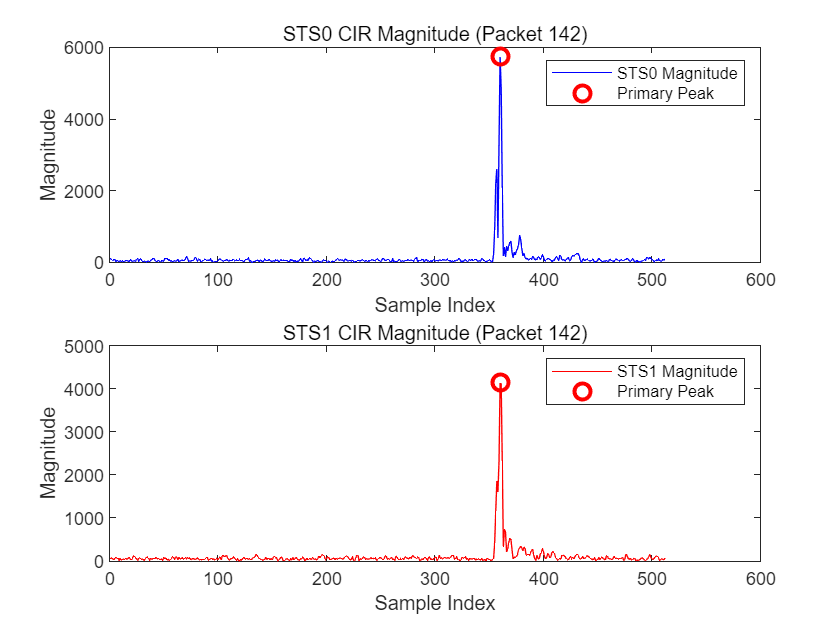

% 视频初始化
% video_filename = '.\Data\金属反射探究距离算法\动态2.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);

% 初始化变量

for i = 1:packets_num
    % i =1 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.4;  % 阈值
    min_peak_distance = 3;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index1_STS1 = locs_STS1(1);

    
    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS1];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS0));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    % theta_radians_main = map_pdoa_to_aoa(phase_difference_main);
    theta_degrees_main = rad2deg(theta_radians_main);

    pdoa_values_main(1,end+1) = phase_difference_main;
    degree_values_main(1,end+1) = theta_degrees_main;
    
  

%     % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布
    %plot(abs(Ipatov_CIR(i,:)));
    
    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');
    
    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');


    %把当前帧写入视频
    frame = getframe(gcf);
  %  writeVideo(v, frame);是因为这个V无法识别导致的
end



% 关闭视频
% close(v);

% disp(['视频已保存为: ', video_filename]);

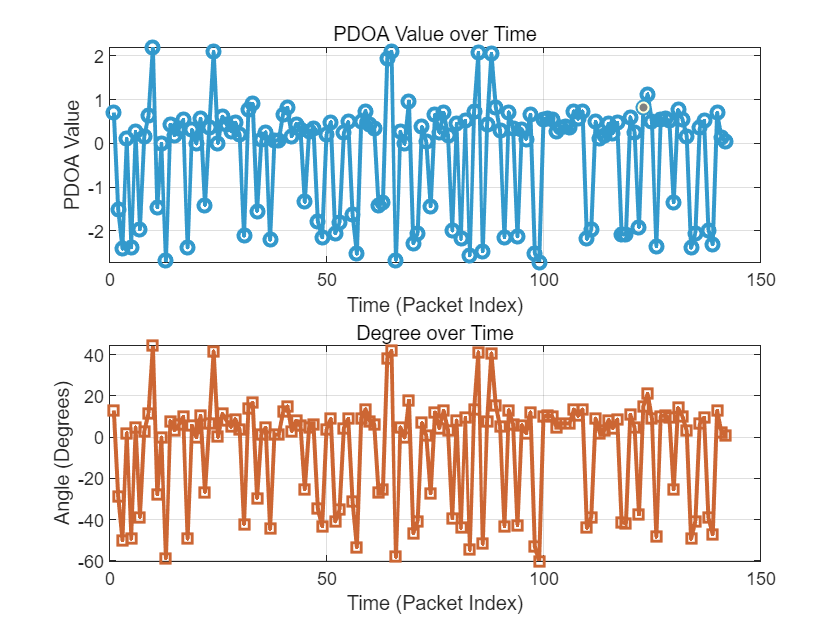

time = 1:length(pdoa_values_main);
figure;
subplot(2,1,1);

plot(time, pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');

grid on;

subplot(2,1,2);
plot(time, degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(pdoa_values_main);
mean_degree = mean(degree_values_main);

% 2. 计算标准差
std_pdoa = std(pdoa_values_main);
std_degree = std(degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.26


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.26



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -5.74


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 25.32


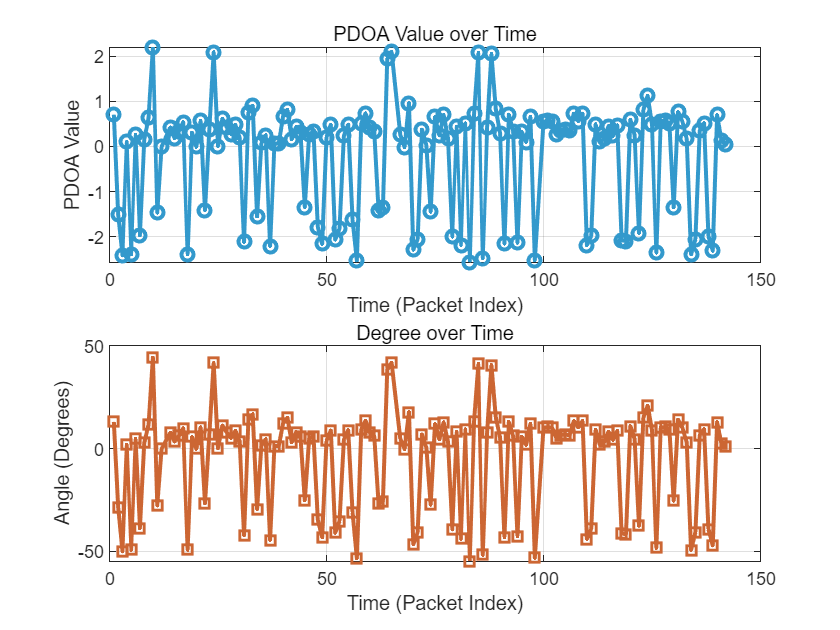

% 原始时间向量
time = 1:length(pdoa_values_main);

% 使用已有的均值和标准差
% mean_pdoa, std_pdoa
% mean_degree, std_degree

% 设置过滤阈值（通常为2或3倍标准差）
threshold = 2;

% 筛选非异常值的逻辑索引
valid_idx = abs(pdoa_values_main - mean_pdoa) <= threshold * std_pdoa & ...
            abs(degree_values_main - mean_degree) <= threshold * std_degree;

% 应用筛选条件
filtered_pdoa = pdoa_values_main(valid_idx);

filtered_degree = degree_values_main(valid_idx);
filtered_time = time(valid_idx);

% 绘图：滤除异常值后的数据
figure;
subplot(2,1,1);
plot(filtered_time, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(filtered_time, filtered_degree, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 再次计算滤波后数据的统计量
mean_filtered_pdoa = mean(filtered_pdoa);
std_filtered_pdoa = std(filtered_pdoa);
mean_filtered_degree = mean(filtered_degree);
std_filtered_degree = std(filtered_degree);

% 输出滤除异常值后的结果
fprintf('【滤除异常值后的结果】\n');

【滤除异常值后的结果】


fprintf('PDOA 平均值: %.2f\n', mean_filtered_pdoa);

PDOA 平均值: -0.21


fprintf('PDOA 标准差: %.2f\n', std_filtered_pdoa);

PDOA 标准差: 1.22



fprintf('\nDegree 平均值: %.2f\n', mean_filtered_degree);


Degree 平均值: -4.59


fprintf('Degree 标准差: %.2f\n', std_filtered_degree);

Degree 标准差: 24.34


% 原始时间向量
time = 1:length(pdoa_values_secondary);

函数或变量 'pdoa_values_secondary' 无法识别。


% 1. 原始数据绘图
figure;
subplot(2,1,1);
plot(time, pdoa_values_secondary, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Raw PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values_secondary, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Raw Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

% 2. 计算均值与标准差

mean_pdoa = mean(pdoa_values_secondary);
std_pdoa  = std(pdoa_values_secondary);
mean_degree = mean(degree_values_secondary);
std_degree  = std(degree_values_secondary);

fprintf('【原始数据统计】\n');
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);
fprintf('PDOA 标准差: %.2f\n', std_pdoa);
fprintf('Degree 平均值: %.2f\n', mean_degree);
fprintf('Degree 标准差: %.2f\n\n', std_degree);

% 3. 异常值滤除（基于2倍标准差）
threshold = 2;
valid_idx = abs(pdoa_values_secondary - mean_pdoa) <= threshold * std_pdoa & ...
            abs(degree_values_secondary - mean_degree) <= threshold * std_degree;

% 4. 提取滤除后的数据
filtered_pdoa = pdoa_values_secondary(valid_idx);
filtered_degree = degree_values_secondary(valid_idx);
filtered_time = time(valid_idx);

% 5. 滤除后绘图
figure;
subplot(2,1,1);
plot(filtered_time, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(filtered_time, filtered_degree, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

% 6. 滤除后统计结果
mean_filtered_pdoa = mean(filtered_pdoa);
std_filtered_pdoa  = std(filtered_pdoa);
mean_filtered_degree = mean(filtered_degree);
std_filtered_degree  = std(filtered_degree);

fprintf('【滤除异常值后的结果】\n');
fprintf('PDOA 平均值: %.2f\n', mean_filtered_pdoa);
fprintf('PDOA 标准差: %.2f\n', std_filtered_pdoa);
fprintf('Degree 平均值: %.2f\n', mean_filtered_degree);
fprintf('Degree 标准差: %.2f\n', std_filtered_degree);
